# **4 Setting up differential equations (Measles)**

Set up the SEIR model of the transmission dynamics of measles in a closed population using **differential equations**: 

We assume that individuals mix randomly and parameter values are given as follows: 

- Population 100,000 people

- Pre-infectious period 8 days

- Infectious period 7 days

- Basic reproduction number 13

- Life Expectancy 70 years

- Initial values (S,E,I,R)=(99999,0,1,0)

## PART I: Setting up differential equations

### 1. Plot a graph for number of susceptible, pre-Infectious, infectious, and recovered populations during 150 days.

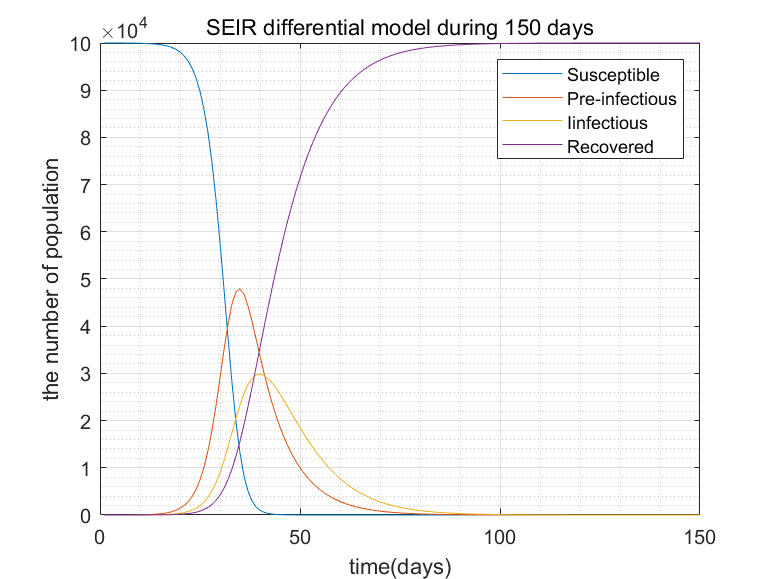

clc; clear; close all;

N = 100000;
pre_inf = 8;
inf = 7;
R_0 = 13;
LE = 70*365;
S0 = 99999; E0 = 0; I0 = 1; R0 = 0;

% variable
beta = R_0/(N*inf);
f = 1/pre_inf;
gamma = 1/inf;

% duration
dt = 1;
tspan = 1:dt:150;

% Allocate memories
S = zeros(length(tspan),1); 
E = zeros(length(tspan),1); 
I = zeros(length(tspan),1); 
R = zeros(length(tspan),1);
S(1) = S0;E(1) = E0;I(1) = I0;R(1) = R0;

% Differential Equation
odeftn = @(t,y) [-beta*y(1)*y(3);...
                 beta*y(1)*y(3)-f*y(2);...
                 f*y(2)-gamma*y(3);...
                 gamma*y(3)];
             
y0 = [S0,E0,I0,R0];
[T,Y] = ode45(odeftn,tspan,y0);

% Plot
figure(1)
plot(T,Y)
grid on; grid minor;
xlabel('time(days)')
ylabel('the number of population')
legend('Susceptible','Pre-infectious','Iinfectious','Recovered')
title('SEIR differential model during 150 days')

### 2. How does the graph change if you change the pre-infectious period to be 5 days and 20 days, respectively?

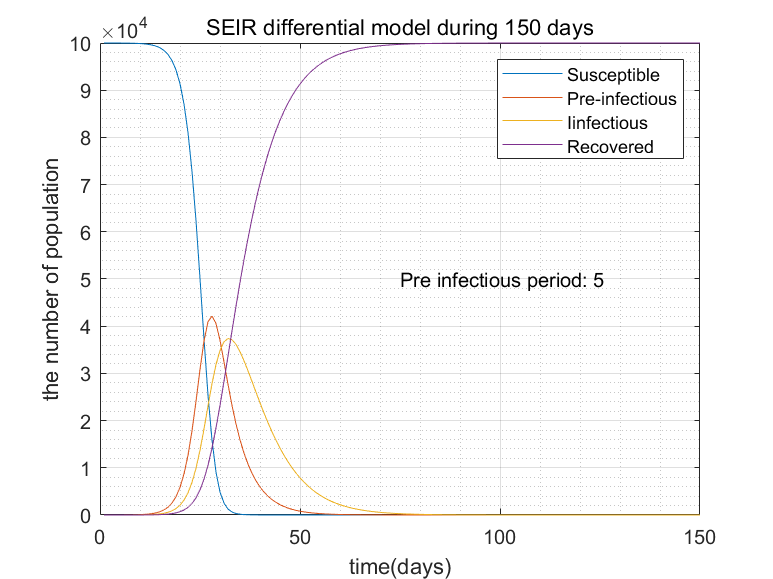

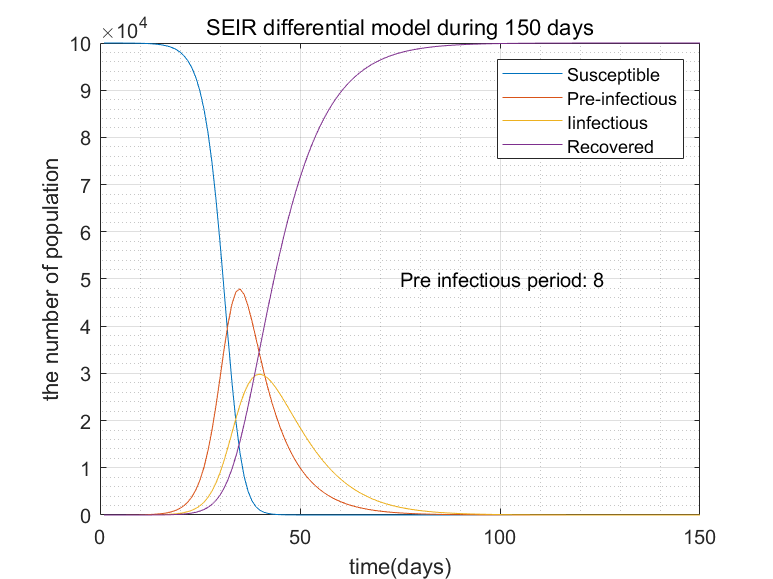

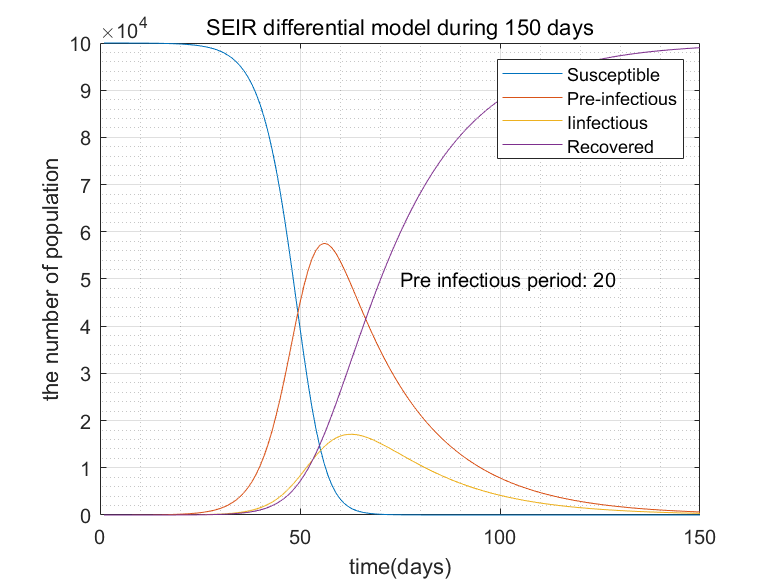

pre_inf = [5,8,20];
f = 1./pre_inf;
for i=1:length(pre_inf)
    odeftn_2 = @(t,y) [-beta*y(1)*y(3);...
                 beta*y(1)*y(3)-f(i)*y(2);...
                 f(i)*y(2)-gamma*y(3);...
                 gamma*y(3)];
    y0 = [S0,E0,I0,R0];
    [T,Y] = ode45(odeftn_2,tspan,y0);
    
    %plot
    figure(i+1)
    plot(T,Y)
    grid on; grid minor;
    txt = {sprintf('Pre infectious period: %d',pre_inf(i))};
    text(150/2,N/2,txt)
    xlabel('time(days)')
    ylabel('the number of population')
    legend('Susceptible','Pre-infectious','Iinfectious','Recovered')
    title('SEIR differential model during 150 days')
end

### 3. What happens to the size of the epidemic (as reflected in the number of people who are immune at the end) as the pre-infectious period is increased? What happens as it is decreased?

## PART Ⅱ: Incorporating births and deaths

### Modify the model to include the births and deaths in each time step and change the parameter values back to original:

### 4. How do the general patterns in the numbers of susceptible and immune individuals differ from those predicted using the difference equations in the last practical?

### 5. You should notice that, although the daily number of new infectious persons and the numbers of susceptible and immune individuals oscillates over time, these oscillations become weaker, and they seem to disappear entirely. This pattern is inconsistent with what happens in many populations in which measles vaccination has not been introduced, measles epidemics occur every two years, which suggests that other factors help to sustain the epidemic cycles. Suggest possible factors which might help to determine the regular patterns in measles cycles.